# **EllipticD**

Complete and incomplete Jacobi form of the elliptic integral D 

## Definition 

**Incomplete elliptic integral B**


$$\mathit{\mathbf{D}}\left(x\left|m\right.\right)\equiv \int_0^x \frac{t^2 \;\mathit{dt}}{\sqrt{\left(1-t^2 \right)\left(1-m\;t^2 \right)}}$$



$$\mathit{\mathbf{D}}\left(x,k\right)\equiv \mathit{\mathbf{D}}\left(x\left|k^2 \right.\right)$$


Domain: $1-x^2 \ge 0$ and $1-mx^2 \ge 0$. If $-\infty <m\le 1$  (or $|k|\le 1$) then $-1\le x\le 1$. If $m>1$ (or $k>1$) then  $|x|<1/\sqrt{m}$. For the specified domain, the  codomain  is real numbers.

Basic features:

$\mathit{\mathbf{D}}\left(-x\left|m\right.\right)=-\mathit{\mathbf{D}}\left(x\left|m\right.\right)$   (odd)

Special values:

$\mathit{\mathbf{D}}\left(0\left|m\right.\right)=0$,   $\mathit{\mathbf{D}}\left(1\left|m\right.\right)=D\left(m\right)$

$\mathit{\mathbf{D}}\left(x\left|-\infty \right.\right)=0$,   $\mathit{\mathbf{D}}\left(x\left|0\right.\right)=\frac{1}{2}\left(\sin^{-1} \left(x\right)-x\sqrt{1-x^2 }\right)$,   $\mathit{\mathbf{D}}\left(x\left|1\right.\right)=\frac{1}{2}\mathrm{ln}\frac{1+x}{1-x}-x$

Identities:


$$\mathit{\mathbf{D}}\left(x\left|m\right.\right)=D\left(\sin^{-1} \left(x\right)\left|m\right.\right),\;\;\;\;\left|x\right|\le 1$$



$$\mathit{\mathbf{D}}\left(x\left|m\right.\right)=\frac{\mathit{\mathbf{F}}\left(x\left|m\right.\right)-\mathit{\mathbf{E}}\left(x\left|m\right.\right)}{m}$$



$$\mathit{\mathbf{D}}\left(x\left|m\right.\right)=\frac{\mathit{\mathbf{D}}\left(x\sqrt{m}\left|m^{-1} \right.\right)}{m\sqrt{m}},\;\;m>1$$


$D\left(\phi \left|m\right.\right)$ is Legendre form of the elliptic integral D. $\mathit{\mathbf{E}}\left(x\left|m\right.\right)$, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ are the Jacobi form of elliptic integral of the first and of the second kind.

**Complete elliptic integral D**


$$D\left(m\right)\equiv \mathit{\mathbf{D}}\left(1\left|m\right.\right)=D\left(\frac{\pi }{2}\left|m\right.\right)$$



$$\mathit{\mathbf{D}}\left(k\right)\equiv D\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter.

Domain: $1-m\ge 0$, (or $|k|\le 1$). For the specified domain, the  codomain is real numbers.

Special values:

$D\left(-\infty \right)=0,$   $D\left(0\right)=\frac{\pi }{4}$,   $D\left(1\right)=\infty$

## Syntax

**Incomplete integral**

Y = EllipticD(X,K)

y = elD(x,k)

Y = mEllipticD(X,M)

y = melD(x,m)

**Complete integral**

Y = EllipticD(K)

y = elD(k)

Y = mEllipticD(M)

y = melD(m)

## Description

**Incomplete integral**

**Y = EllipticD(X,K)** returns the Jacobi form of the elliptic integral  $\mathit{\mathbf{D}}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **EllipticD** is the wrapper function which calls the functions **elD** element-wise via the function **ufun2**.

**y = elD(x,k)** returns  value of the Jacobi form of the elliptic integral  $\mathit{\mathbf{D}}\left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **elD** is the wrapper function which calls the functions **melD**.

**Y = mEllipticD(X,M) **returns the Jacobi form of the elliptic integral  $\mathit{\mathbf{D}}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mEllipticD** is the wrapper function which calls the functions **melD** element-wise via the function **ufun2**.

**y = melD(x,m)** compute the value of the Jacobi form of the elliptic integral  $\mathit{\mathbf{D}}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **melD **call the Carlson's functions **rf **and** rd **for calculation of $\mathit{\mathbf{D}}\left(x\left|m\right.\right)$ ([1-2]).

**Complete integral**

**Y = EllipticD(K) **returns the value of the complete elliptic integral $\mathit{\mathbf{D}}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticD** is the wrapper function which calls the functions **elD** element-wise via the function **ufun1**.

**y = elD(k)** returns the value of the complete elliptic integral  $\mathit{\mathbf{D}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elD** is the wrapper function which calls the functions **melD**.

**Y = mEllipticD(M)** returns the value of  the complete elliptic integral $D\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticD** is the wrapper function which calls the functions **melD** element-wise via the function **ufun1**.

**y = melD(m)** compute value of  the complete elliptic integral  $D\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melD **call the function **mcelB **which call the Carlson's functions **rf **and** rd** for calculation of $D\left(m\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
x = 0.5;
[elD(x,k), EllipticD(x,k), melD(x,k^2), mEllipticD(x,k^2)]

ans =    0.046186768767871   0.046186768767871   0.046186768767871   0.046186768767871


[elD(k), EllipticD(k), melD(k^2), mEllipticD(k^2)]

ans =    0.873152581892676   0.873152581892676   0.873152581892676   0.873152581892676


m = 0.5; % |m|<1 
[elD(sqrt(m)), EllipticD(sqrt(m)), melD(m), mEllipticD(m)]

ans =    1.006861592507393   1.006861592507393   1.006861592507393   1.006861592507393


Accuracy

melD(0.02) % =0.7913 (Jahnke, Emde, 1945, pp 83)

ans = 0.7914

melD(0.52)  % =1.0210 (Jahnke, Emde, 1945, pp 83)

ans = 1.0210

melD(0.94) %  =1.8625 (Jahnke, Emde, 1945, pp 83)

ans = 1.8625

Accuracy. 

fprintf('%.16g\n',melD(1/4,-4)) % Maple 18D   0.004955968219520414 23

0.004955968219520415


fprintf('%.16g\n',elD(1e-9)) % Maple 18D   0.7853981633974483 0991

0.7853981633974483


Special values

m = -2;
x = -0.5;  % |x| <= 1
melD(0,m)

ans = 0

disp(melD(1,m) - melD(m))  % m < 1 !!!

     0



melD(x,-inf)

ans = 0

disp(melD(x,0) - (asin(x) - x*sqrt(1 - x^2))/2)

     0



disp(melD(x,1) - 1/2*log((1+x)/(1-x)) + x)

     1.110223024625157e-16



melD(x,-inf)  

ans = 0

melD(-inf)

ans = 0

disp(elD(0) - pi/4)

     0



disp(elD(1)-1)

   Inf



Identities

m = -2;
x = 0.5; % |x| <= 1
mEllipticD(-x,m) + mEllipticD(x,m)

ans = 0

disp(mEllipticD(x,m) - mpEllipticD(asin(x),m))

     0



k = 0.99995;
disp(EllipticD(x,k) - (EllipticF(x,k) - EllipticE(x,k))/k^2)

     2.775557561562891e-17



m = 0.99995;
x = 0.5;
disp(mEllipticD(x,m) - (mEllipticD(x*sqrt(m),1/m)/sqrt(m)/m))

     6.938893903907228e-18



**Vector input**

m = [1, 2, 3]';
x = 0.5;
disp(mEllipticD(x,m) - (mEllipticD(x*sqrt(m),1./m)./sqrt(m)./m))

   1.0e-16 *

                   0
  -0.208166817117217
                   0



**Matrix input**

m = [1, 2, 3; 4, 5, 6]';
x = 0.25;
disp(mEllipticD(x,m) - (mEllipticD(x*sqrt(m),1./m)./sqrt(m)./m))

   1.0e-17 *

                   0                   0
  -0.086736173798840  -0.086736173798840
   0.173472347597681   0.086736173798840



## **Plot **

**Example 1**

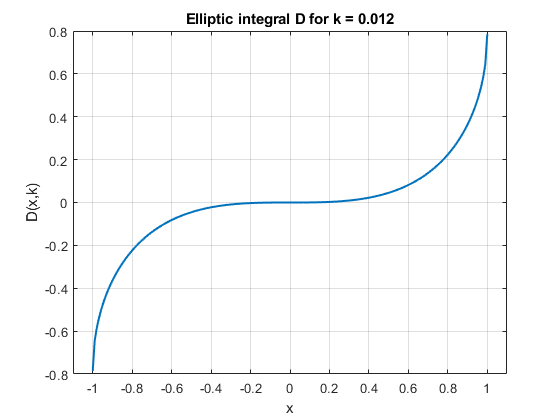

figure
x=-1:0.01:1;
k = 0.012;
plot(x,EllipticD(x,k),'LineWidth',1.5)
xlabel('x')
ylabel('D(x,k)')
xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Elliptic integral D for k = %g',k))
grid on

**Example 2**

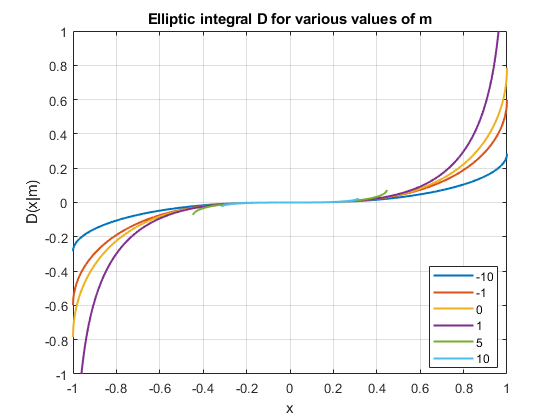

figure
X = -1:0.001:1;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mEllipticD(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1 1])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral D for various values of m')
xlabel('x')
ylabel('D(x|m)')

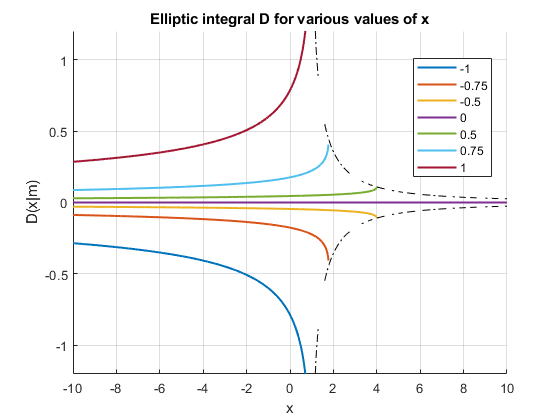

figure
hold on
M = -10:0.01:10;
X = [-1,-0.75,-0.5,0,0.5,0.75,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticD(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -1.2 1.2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral D for various values of x')
xlabel('x')
ylabel('D(x|m)')
M = 0:0.1:10;
E = mEllipticD(1./sqrt(abs(M)),M);
plot(M,E,'k-.')
plot(M,-E,'k-.')
hold off

**Example 3**

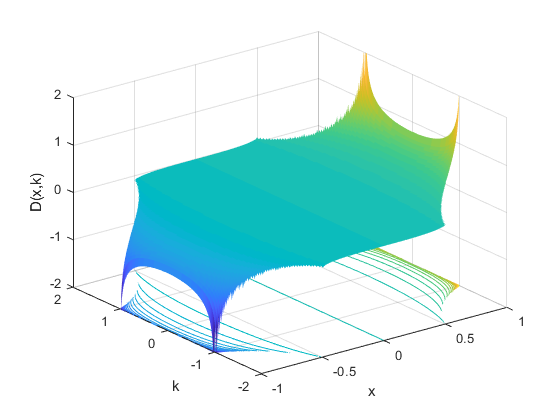

figure
x=-1:0.01:1;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,EllipticD(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('D(x,k)')
zlim([-2 2])
grid on

**Example 4**

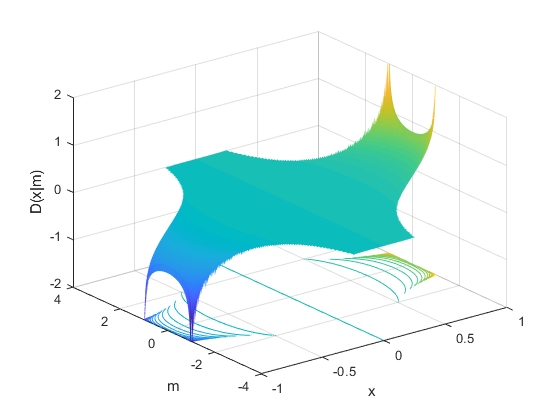

figure
x=-1:0.01:1;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,EllipticD(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('D(x|m)')
zlim([-2 2])
grid on

**Example 5**

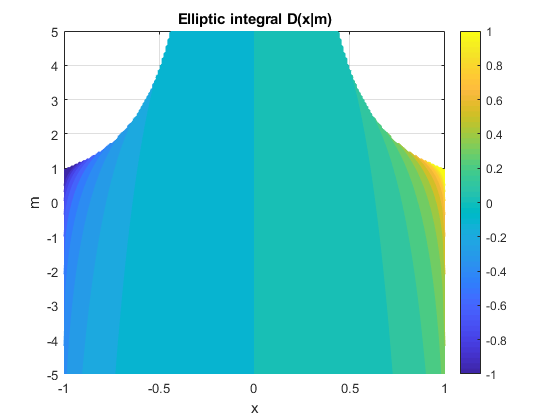

figure
f = @(x,m)mEllipticD(x,m);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral D(x|m)')
xlabel('x')
ylabel('m')
colorbar
grid on

**Example 6**

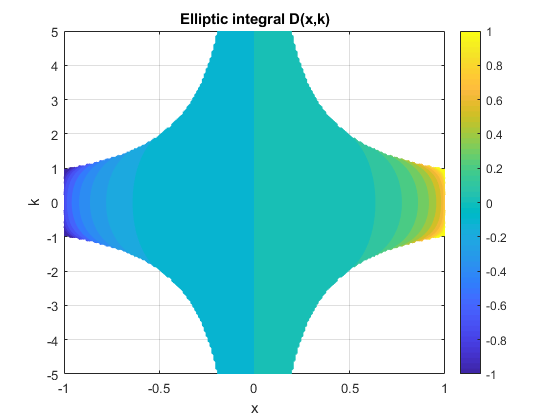

figure
f = @(x,k)EllipticD(x,k);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral D(x,k)')
xlabel('x')
ylabel('k')
colorbar
grid on

**Example 7**

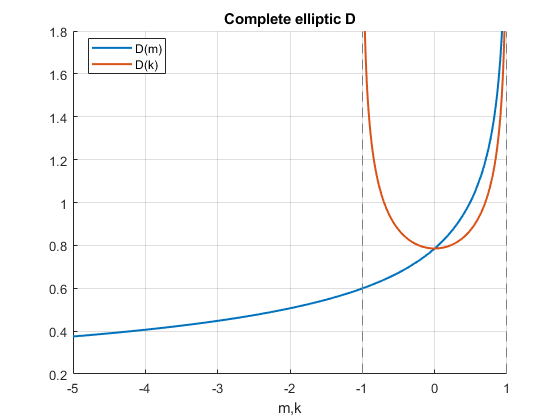

figure
hold on
fplot(@(m) mEllipticD(m),'LineWidth',1.5)
fplot(@(k) EllipticD(k),'LineWidth',1.5)
title('Complete elliptic D')
legend('D(m)','D(k)','Location','best')
xlabel('m,k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

[3] A. Erd´elyi et al., Higher Transcendental Functions Vol. II, California Institute of

Technology - Bateman Manuscript Project, 1953-1955 McGraw-Hill Inc. 

[4] E.Jahnke, F. Emde, Tables of Functions, 4th ed, Dover,  1945

## See Also